# Sellmeier Analysis

% Run main.m for workspace
main;


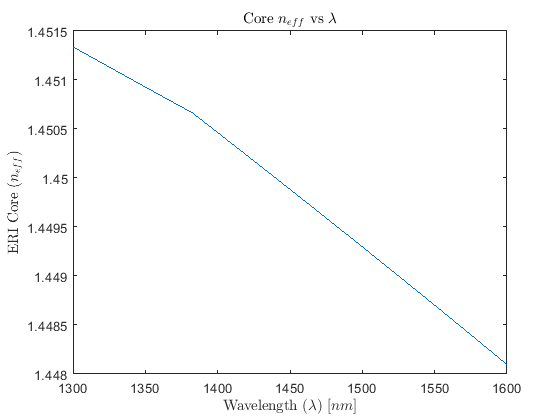

% Core Mode ERI
plot(i,temp1); title('Core $n_{eff}$ vs $\lambda$',"Interpreter","latex");
ylabel('ERI Core ($n_{eff}$)','Interpreter',"latex"); xlabel('Wavelength ($\lambda$) [$nm$]','Interpreter',"latex");

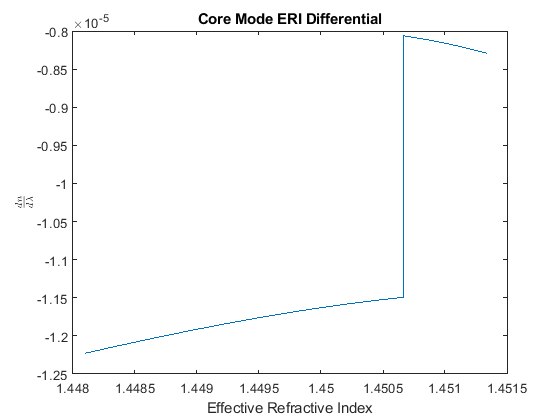

% Calculate diff of core mode ERI
df = diff(temp1)/step;
plot(temp1(1:end-1),df); title("Core Mode ERI Differential");
xlabel("Effective Refractive Index"); ylabel("$\frac{dn}{d\lambda}$","Interpreter","latex");

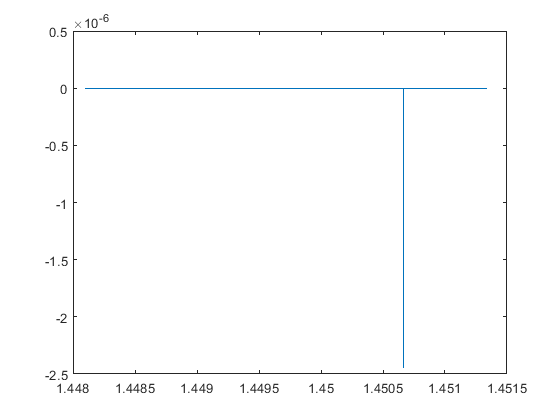


ddf = diff(df);
%plot(temp1(1:end-2),ddf);

is_discont = ddf < 0;
n_discont = temp1(find(is_discont,1)) % point where discontinuity occurs

ans = 1.4507

% Find Change Points

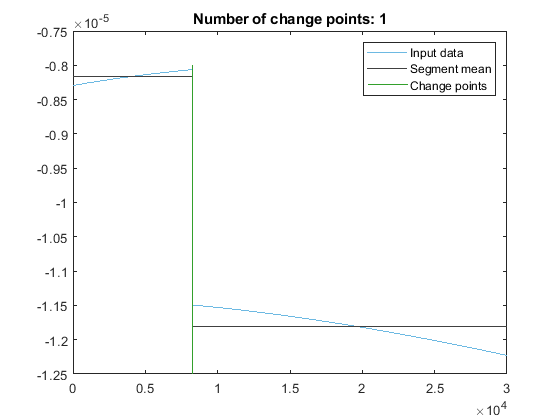

% Find change points
[changeIndices,segmentMean] = ischange(df,'variance','Threshold',100000);

% Display results
clf
plot(df,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

% Plot segments between change points
plot(segmentMean,'Color',[64 64 64]/255,'DisplayName','Segment mean')

% Plot change points
x2 = repelem(find(changeIndices),3);
y = repmat([ylim(gca) NaN]',nnz(changeIndices),1);
plot(x2,y,'Color',[51 160 44]/255,'LineWidth',1,'DisplayName','Change points')
title(['Number of change points: ' num2str(nnz(changeIndices))])

hold off
legend

clear segmentMean x2 y